# **DATA 6. Synthetic Epilepsy EEG (Simulated; Not Human Subject Data)**

% (C) 2026 Moo K. Chung
% University of Wisonsin-Madison
%
% This repository includes a synthetic EEG dataset designed for methodological
% validation, simulation, and algorithm testing in the context of juvenile
% myoclonic epilepsy (JME). 
% 
% No synthetic signal corresponds to any human participant’s EEG recording.
% The dataset therefore does not constitute human subjects data under NIH definitions.
% The data are synthesized exclusively for methodological validation,
% simulation, and algorithm testing, and are intended solely as a validation
% dataset.
%
% Scientific context and motivation are drawn from:
%
% @article{struck2025juvenile,
%   title={Juvenile Myoclonic Epilepsy Imaging Endophenotypes and Relationship With Cognition and Resting-State EEG},
%   author={Struck, Aaron F and Garcia-Ramos, Camille and Gjini, Klevest and Jones, Jana E and Prabhakaran, Vivek and Adluru, Nagesh and Hermann, Bruce P},
%   journal={Human Brain Mapping},
%   volume={46},
%   pages={e70226},
%   year={2025},
% }
%
% If you are using the data, reference this paper. 

load EEG

% Synthetic Dataset composition:
%   The synthetic dataset consists of two cohorts: 50 healthy controls and
%   50 juvenile myoclonic epilepsy (JME) subjects. Each synthetic subject
%   contains multichannel resting-state EEG time series recorded on a
%   256-channel montage over a fixed duration 3 seconds.

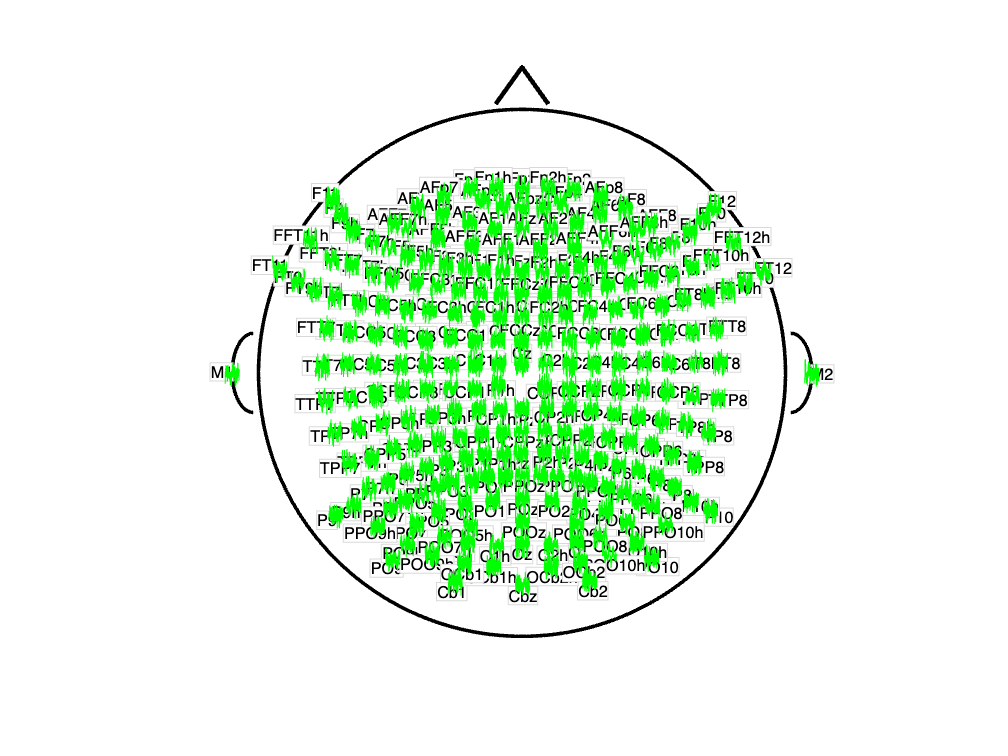

eeg256_layout_plot(EEGchannel)
subjIdx=1; %Subject ID
eeg256_timeseries_overlay(EEGchannel, Controls(:,:,subjIdx));

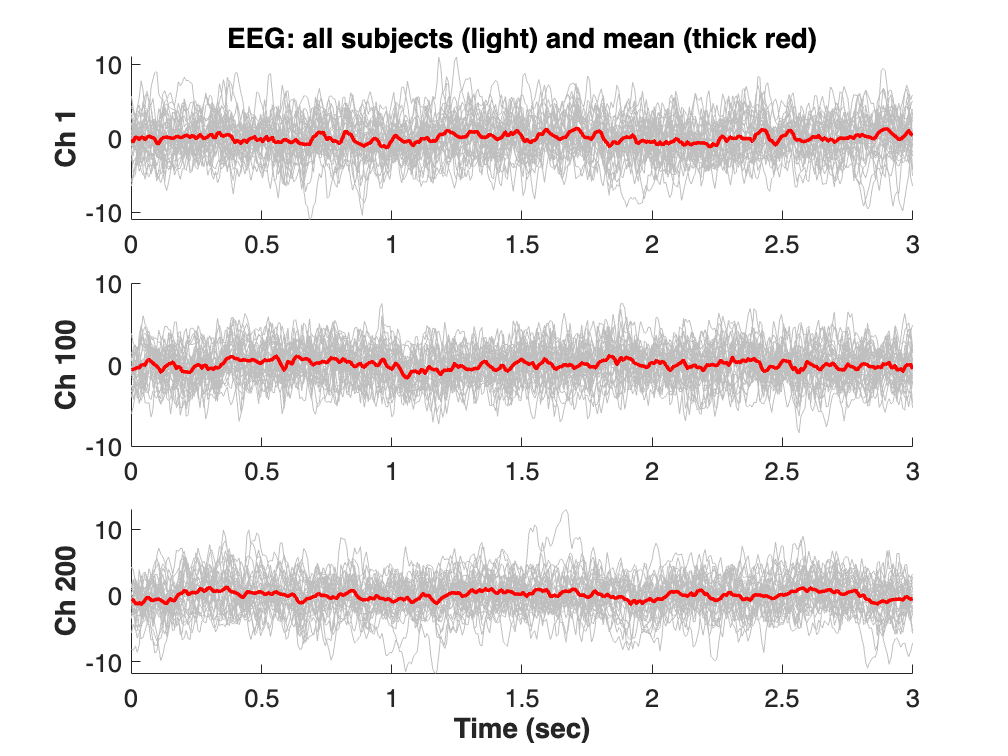

% It's difficult to see the pattern for each channel. 
% Channel 1, 100 and 200:
EEG_display(Controls, [1 100 200]);

## Mean and Variance Preserving Permutation Resampling

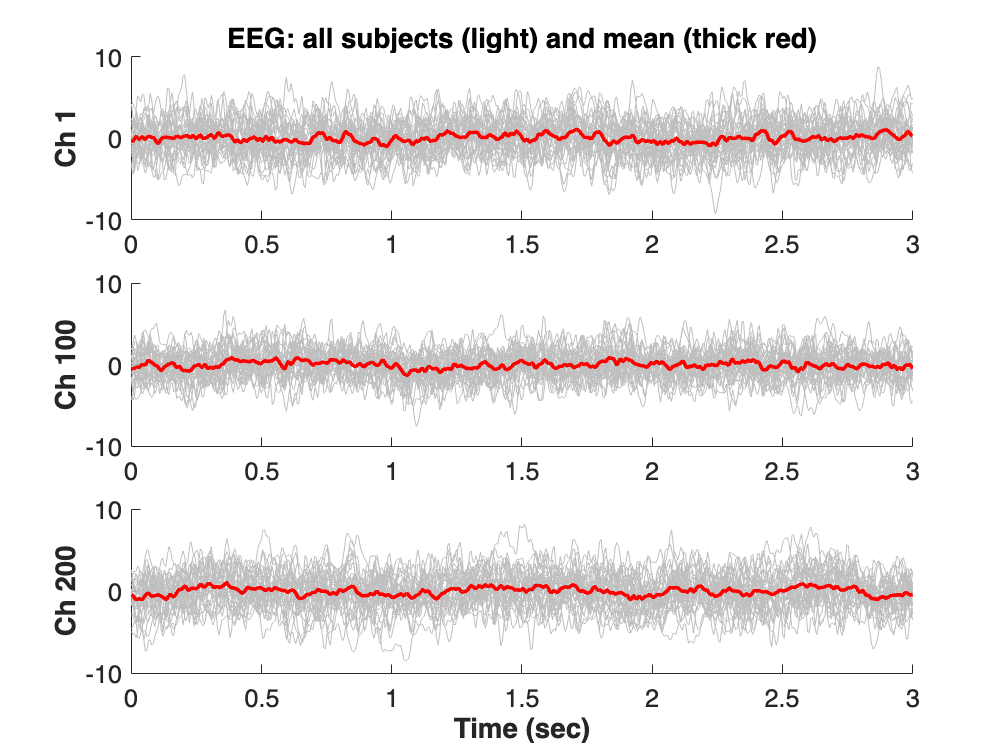

% This permutation strategy was first introduced in:
%
%   Wang, Y., Ombao, H., & Chung, M. K. (2018).
%   Topological data analysis of single-trial electroencephalographic signals.
%   Annals of Applied Statistics, 12(3), 1506–1531.
%
% The permutation is performed independently within each channel and
% frequency bin across subjects. As a result, the empirical distribution
% (and hence the mean and variance) of Fourier coefficients is preserved
% at every channel–frequency location, while subject-wise multichannel
% dependence is destroyed.
%
% Consequently, the across-subject mean signal remains identical before and after permutation, 
% whereas individual reconstructed subject time series differ due to reassignment 
% of coefficients. This explains why the mean EEG trace appears unchanged while individual
% subject traces vary.
%
% If you are using this specific permutation test, please cite the paper
% above.

ControlsF = EEG_Fourier(Controls); % Fourier transform
ControlsFP = EEG_Fourier_permute(ControlsF); % Permutation
ControlsFPR = EEG_Fourier_reconstruct(ControlsFP, 500);
EEG_display(ControlsFPR, [1 100 200]);

## From 1-simplex to 2-simplex

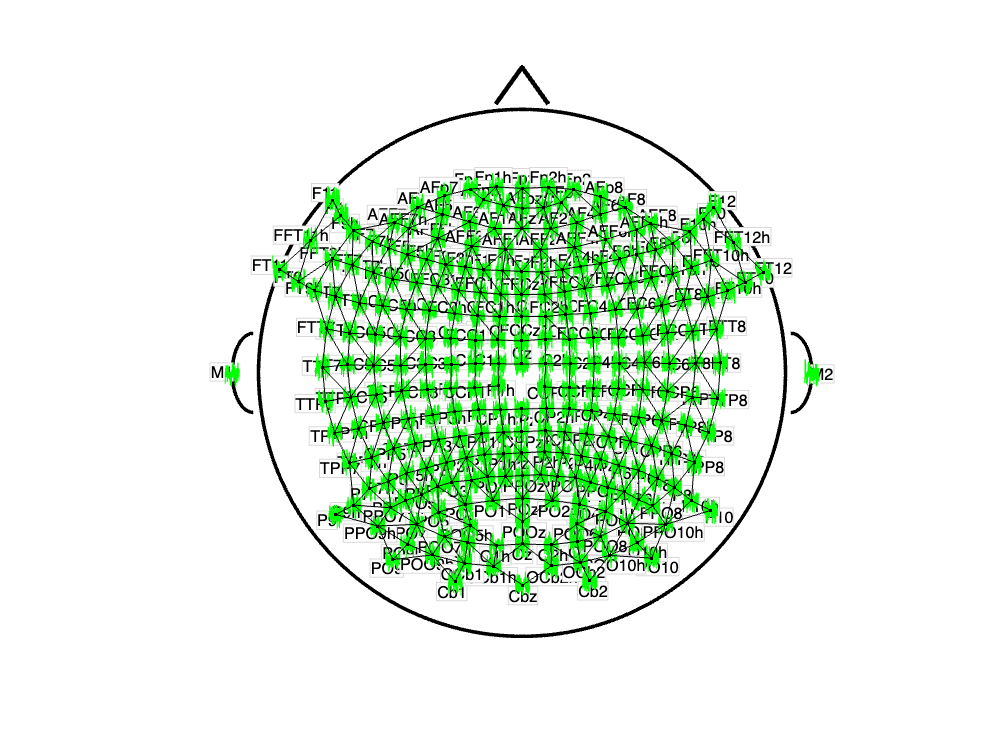

% In EEG sensor space, typical inter-electrode spacing depends on the montage.
% As a rough guide:
%   10–20 system: ~6–7 cm
%   10–10 system: ~3–4 cm
%   10–5 system / dense arrays (128–256 channels): ~1.5–2.5 cm
%
% For a 256-channel cap, the median nearest-neighbor (NN) distance in 3D
% electrode space is often around ~2 cm (commonly ~1.8–2.2 cm, depending on
% head size, cap model, and how aggressively facial/neck electrodes are used).
%
% Thus, two channels are connected by an (undirected) edge if their 3D
% inter-electrode distance is smaller than 1.8cm.

eeg256_layout_plot(EEGchannel)
eeg256_timeseries_overlay(EEGchannel, Controls(:,:,subjIdx));
S = eeg256_build_mesh(EEGchannel,1.7);
eeg256_graph_overlay(S);

## PROJECT 10. Hodge Theory of Directed Networks

% Goal
% The goal of this project is to develop a principled framework for analyzing
% multivariate time series data as signals defined on a simplicial complex.
% By leveraging the Hodge Laplacian, the project aims to characterize directed
% connectivity and higher-order interaction structure through spectral
% expansion of edge-based signals.

% Description
% This project analyzes multivariate time series data by explicitly modeling
% the geometry and topology of the underlying measurement domain and the
% induced graph and simplicial complex structure. Rather than treating
% individual time series as independent signals, the data are formulated as
% signals defined on a geometric complex, enabling the use of the Hodge
% Laplacian to model directed connectivity. Directed interactions may be
% obtained from transfer entropy or other causal or information-theoretic
% measures; in practice, transfer entropy often provides robust empirical
% performance.
%
% Using this representation, time-varying edge signals are analyzed by
% expanding them in the eigenbasis of the 1-Hodge Laplacian, analogous to a
% Fourier series expansion. The resulting expansion coefficients are then
% analyzed to characterize the dynamics of directed connectivity.This spectral 
% representation enables investigation of whether connectivity patterns
% exhibit traveling-wave–like behavior, analogous to traveling waves often
% observed in node-level signals.  Permutation-based inference is
% used to assess the statistical significance of observed spectral patterns.
%
% Learning Outcomes
% This project develops the ability to model multivariate time series as
% signals on a simplicial complex and to analyze directed connectivity using
% the Hodge Laplacian. Participants gain experience expanding edge-based
% signals in the Hodge eigenbasis and using permutation-based synthetic data
% as null models. The project builds intuition for how geometry, topology,
% and spectral representations shape higher-order interaction dynamics.